# Compression Ratio Calcs

% Geometry
d_i = 1.835/39.37; % m
d_a = 2.52/39.37; % m
d_m = (d_i + d_a)/2; % m
beta1 = 30; % [degrees] (assumed beta1 = beta2)
eff = .6; % efficency

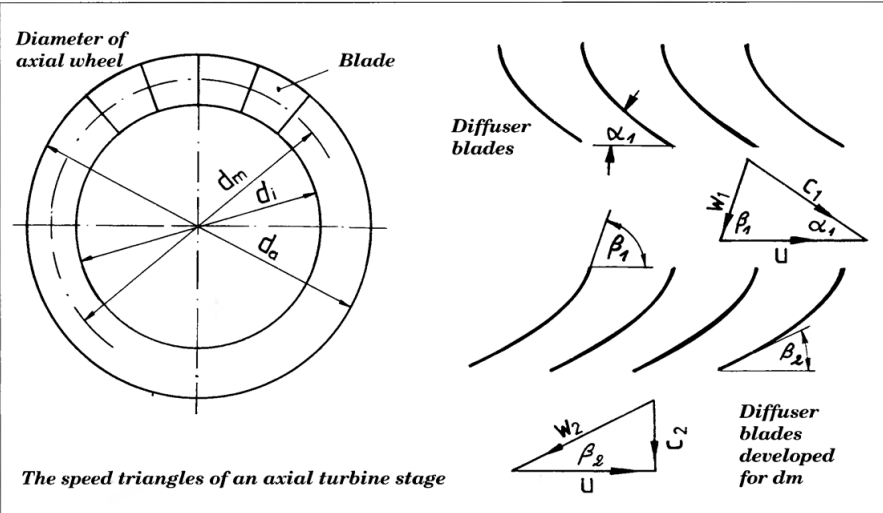

% Properties
RPM = [50000, 55000, 60000, 65000, 70000, 75000, 80000, 85000]

RPM =        50000       55000       60000       65000       70000       75000       80000       85000


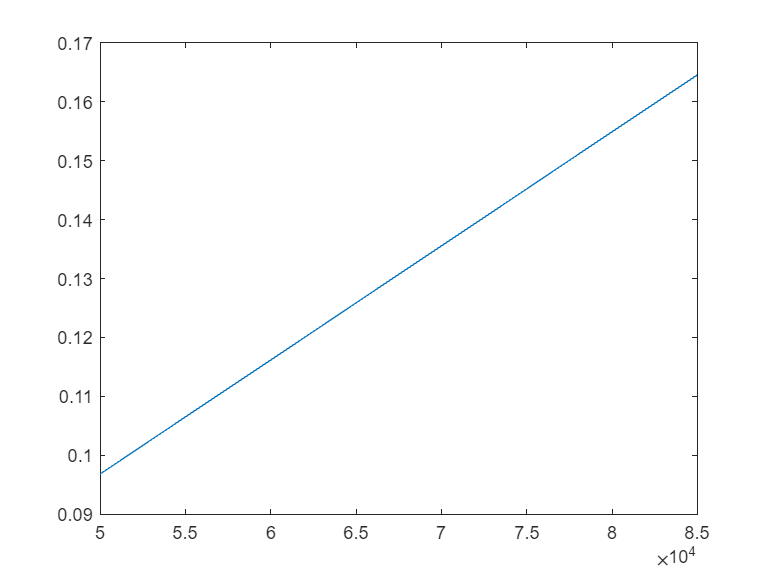

n_max = RPM/60; % % max rotational speed [1/s]
u_max = n_max*(d_a * pi); % max peripheral speed [m/s]
u = d_m * pi * n_max; % mean peripheral speed [m/s]
c_out = u * tand(beta1); % outlet speed [m/s]

gas_T = 873; % max gas temp [K]
rho_N = 1.225; % avg density of air [kg/m^3]
rho = rho_N * (273/gas_T); % density of air given temp [kg/m^3]
outlet_A = (d_a^2 - d_i^2)*pi/2; % Outlet Area [m^2]

m_dot = outlet_A .* c_out * rho; % mass flow rate out of outlet (assumed just air) [kg/s]
F = m_dot .*c_out; % estimated thrust [N]

Cp = 1000; % specific heat of air costant pressure [J/kg*K]
T1 = 293; % temperature before inlet [K]
compression_ratio = (((.6.*u.^2)./(Cp*T1))+1).^(1/0.285); % compression ratio of compressor
P_W = (m_dot.*u.^2)./1000; % Shaft power [KWatt]


plot(RPM,m_dot)

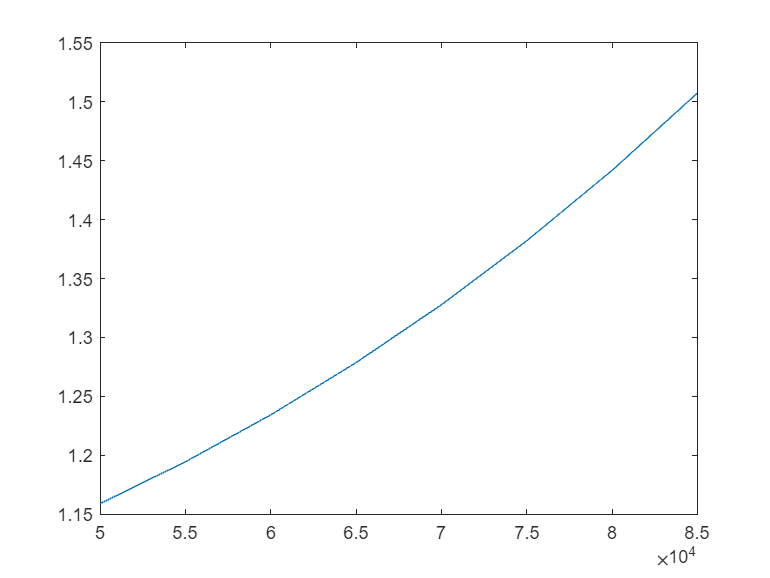

plot(RPM,compression_ratio)

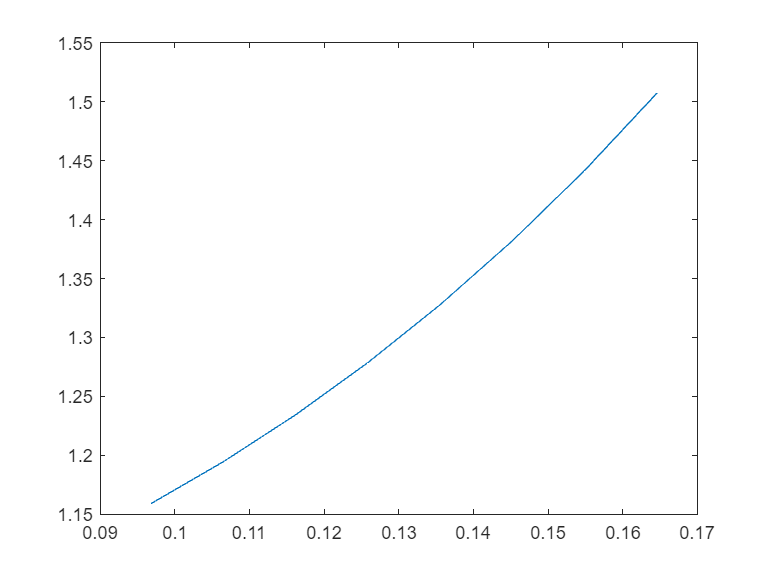

plot(m_dot,compression_ratio)

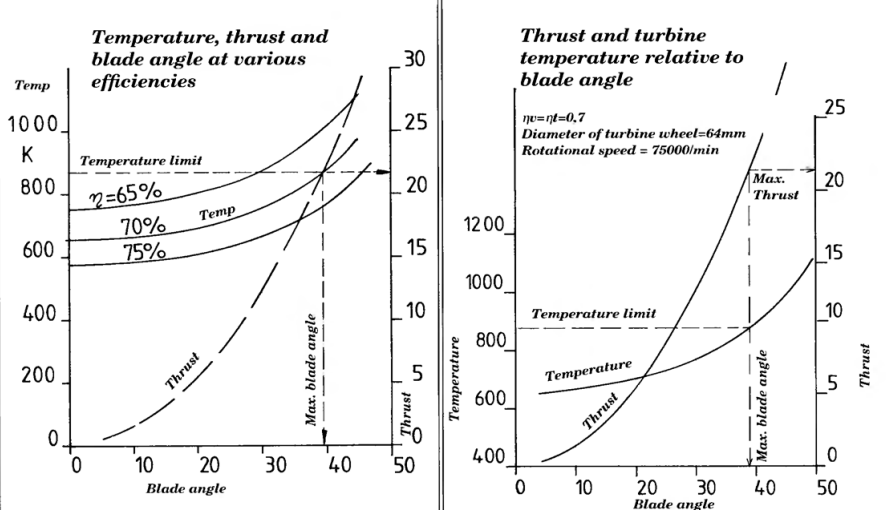

% Thermo analysis 
delta_T = 743 - T1; % [K]
delta_d = .000016 * delta_T * d_a *1000;


d_comp = .066; % Major compressor diameter [m]
h_blade = .005; % blade height at compressor exit [m]

delta_T = (T1/eff)*(compression_ratio.^.286 - 1);
T_compressor = T1 + delta_T; % Temperture after the compressor

P1 = 101300; % Total pressure at inlet [Pa]
R = 287; % [J/kg/K]
Beta2 = 65;
u2 = n_max*(d_comp*pi);

rho_compressor = (compression_ratio.*P1)./(T_compressor.*R);

c_m = m_dot./(rho_compressor.*pi*d_comp*h_blade); %

c_u = u2 - (c_m/tan(Beta2));

alpha = atand(c_m./c_u);